# Lab session IV:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 3 points

- Exercise 3: 3 points

- Exercise 4: 3 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to 

# Exercise 1:

The point p has coordinates

p_A = [3, 4]';

on a frame {A}, and coordinates

p_B = [-2.5, 0.5]';

on a frame {B}.

It is known that the angle between $x$-axis of frame {A} and the$y$ axes of the frame {B} is 30 deg counterclockwise.

##  1.1 Which are the coordinates of the origin of A seen from B?

Using the formula of rotation + displacement


$${}^Bp={}^BR_A\;{}^Ap+{}^Bd_{B\to A}$$


%First, we build the matrix
%To have an angle of 30 deg between the x axis on frame A and the y axis of frame B
%we need to first rotate 90 degrees and then rotate 30 deg in the opposite direction
angle = - 90 + 30;
B_R_A = [cosd(angle), sind(angle); -sind(angle), cosd(angle)];
%Then we calculate the point
B_d_BA = p_B - B_R_A * p_A;

##  1.2 Which are the coordinates of the origin of B seen from A?

A_R_B = B_R_A';
A_d_AB = - A_R_B * B_d_BA;

##  1.3 Which are the coordinates of a point q expressed in A if 

q_B = [3,1]';
% We know the rotation matrix, dBA & point Q seen from B, then:
q_A = A_R_B * q_B + A_d_AB;

# Exercise 2:

 Let {A}, {B} and {C}, be 3 different reference frames. From them we know that:

- The origin of B with respect A is

AoB = [3,1,-2]';

- The origin of C with respect B is

BoC = [-3, 1,-2]';

- The three frames has different orientations in space. In fact:  

- The set of Euler angles stored in $\eta$ as $\eta = (\psi,\theta,\phi)$

eta = [25;145;30]; % Expressed in degrees

                 represent 3 consecutive rotations about z, y, and x respectively that allows to transform vectors from {A} to {B}

- The quaternion

q = 1/7*[-sqrt(3)*3.5;3;-1;-1.5];

                 allows to express in {B} a vector defined in {C}, if {C} and {B} had the same origin

Let in addition v1 and v2 to be points which coordinates are known in  {C}.

v1_C = [0;2;0];
v2_C = [0;2;5];

With the information provided above determine:

##  2.1.1 The affine** expression** that allows to relate a vector originally given in {C} to {B}. Note that no calculations have to be provided here, only the expression which is not a matrix.


$${}v_B=\left\lbrack \begin{array}{cc}
\left({}q^2_0-{}q^Tq\right){}I_3+2\left(q{}q^T\right)+2{}q_0{}{\left\lbrack q\right\rbrack }_x & {}^Bd_{B->C}\\
{}0_{1\mathrm{x3}} & 1
\end{array}\right\rbrack *{}v_c$$


## 2.1.2 Implement a function called rotVbyq that provided a vector and a quaternion rotates the vector using quaternion multiplications. Test it and commet why do you think it is well implemented.

##  2.2 The affine matrix that allows to express a vector originally given in {C} to {A}.

%Affine matrix from C to B
stoich = [       0, -v2_C(3),  v2_C(2);
           v2_C(3),        0, -v2_C(1);
          -v2_C(2),  v2_C(1),        0]

stoich =      0    -5     2
     5     0     0
    -2     0     0


B_R_C = (q(1)^2 - q(2:4)' * q(2:4)) * eye(3) + 2 * (q(2:4) * q(2:4)') + 2 * q(1) * stoich;
B_A_C = [B_R_C(1,1), B_R_C(1,2), B_R_C(1,3), BoC(1);
         B_R_C(2,1), B_R_C(2,2), B_R_C(2,3), BoC(2);
         B_R_C(3,1), B_R_C(3,2), B_R_C(3,3), BoC(3);
                  0,          0,          0,      1]

B_A_C =     0.8673    8.5378   -3.6478   -3.0000
   -8.7827    0.5408    0.0612    1.0000
    3.2804    0.0612    0.5918   -2.0000
         0         0         0    1.0000


%Affine matrix from B to A
A_R_B = eAngles2rotM(eta(1), eta(2), eta(3));
A_A_B = [A_R_B(1,1), A_R_B(1,2), A_R_B(1,3), AoB(1);
         A_R_B(2,1), A_R_B(2,2), A_R_B(2,3), AoB(2);
         A_R_B(3,1), A_R_B(3,2), A_R_B(3,3), AoB(3);
                  0,          0,          0,      1]

A_A_B =    -0.7094   -0.2432    0.6615    3.0000
   -0.4096    0.9061   -0.1061    1.0000
   -0.5736   -0.3462   -0.7424   -2.0000
         0         0         0    1.0000


%Affine matrix from C to A
A_A_C = A_A_B * B_A_C

A_A_C =     3.6909   -6.1478    2.9644    3.5620
   -8.6611   -3.0133    1.4867    3.3470
    0.1076   -5.1298    1.6317    0.8593
         0         0         0    1.0000


## 2.3 The vectors v1_C and v2_C forms a segment. Make a 3d plot (plot3() in matlab), representing how the segment is seen on {A} in red, on {B} in blue and on {C} in green.

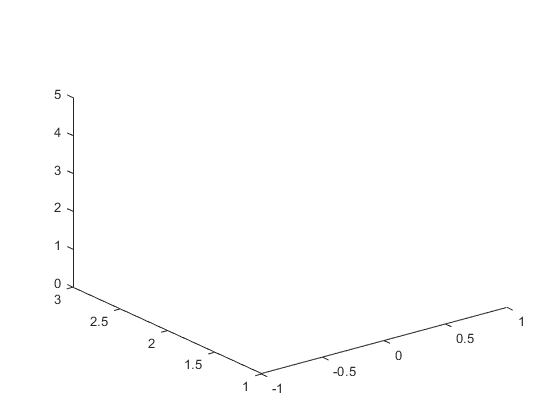

%In C
plot3(v1_C(1), v1_C(2), v1_C(3), v2_C(1), v2_C(2), v2_C(3), 'g')

%In B
plot3(v1_B(1), v1_B(2), v1_B(3), v2_B(1), v2_B(2), v2_B(3), 'b')

Undefined function or variable 'v1_B'.

%In A
plot3(v1_A(1), v1_A(2), v1_A(3), v2_A(1), v2_A(2), v2_A(3), 'r')

# Exercise 3:

The points described by the columns of the matrix A 

A = load('AEx3.mat');
A = A.A;

are points contained into a circle, and they are defined in a world frame W.

A camera is situated at point

wc = [1; 6; 1];

 defined in the world frame. Moreover the orientation of this camera frame is achieved by rotating the world frame 90 degs about its y axis followed by -20 degrees about the resulting z axis.

If the camera has a focal length of 1/34 m:

##  3.1 Make a plot with the view of the points of the circle projected into the camera plane.

##  3.2 Make also a 3D plot where all the scene is drawn in the world coordinates. The scene must contain the 2 reference frames (2 orthogonal sets of vectors) and the circle points. 

You can use the provided function cameraproj.

# Exercise 4:

The columns of the next matrix, represents the coordinates od 4 points defined in a world frame.

A = load('AEx4.mat');
A = A.A;

From this 4 points, two segments are defined. The segment one, goes from the point defined by the first column to the point defined by the second column. The second segment is defined by the other two points.

 A camera frame is seeing the scene. The origin of the world frame seen from the camera frame is given by the vector

wc = [4.665;3.735;-0.5395];

And the orientation of the camera frame is obtained after rotating the world frame -150 degs about the direction

u = [0.01;-.2;1];

With the data provided determine:

## 4.1 The minimum angle that both segments forms (hint, they intersect)

## 4.2 The angle that both segments forms in the image plane

## 4.3 Deliver a 3D representation of the scene with all the coordinates refered to the world frame

## 4.4 Deliver the same 3D scene representations but with all the coordinates refered to the camera frame